%This code reproduces Extended Fig3 from the second rebuttal submitted to Nature2020
%paper (Nienhuis et al., 2020). It needs v1 dataset provided by Jaap Nienhuis

v1 = load ('V1\GlobalDeltaData_v1.mat');%provided by Jaap Nienhuis, now available at https://osf.io/s28qb/
%v09 = load ('V0.9\GlobalDeltaData_v0.9.mat') %from https://github.com/jhnienhuis/GlobalDeltaChange

load 'V1/BasinID2';
BasinID2 = double(BasinID2);

%Max 100
Max_deltas100 = readtable('EE_Max100Big_polys_change.csv'); % From https://github.com/FlorinZai/Global_Delta_Check

Max_deltas100_orig = readtable('GlobalDeltaMax100ID.csv'); %From https://github.com/jhnienhuis/GlobalDeltaChange/tree/master/land_area_change
[~,DeltaID_Max100] = ismember(Max_deltas100.ID, BasinID2);
[~,DeltaID_Max100_orig] = ismember(Max_deltas100_orig.BasinID2, BasinID2);
Max_deltas100_change = Max_deltas100.change2/28;


%replace original large deltas in V1 with corrected Max100 deltas(our data)
v1.ee.net_max100replaced = v1.ee.net_aqua

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    


for i = 1:numel(Max_deltas100_change)
v1.ee.net_max100replaced(DeltaID_Max100(i)) = Max_deltas100_change(i)
end

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

v1 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
         delta_name: {66×1 cell}
      delta_name_id: {66×1 cell}
                 ee: [1×1 struct]
           DeltaSLR: [10848×1 double]
          shelf_len: [10848×41 double]
      shelf_len_lat: [10848×41 double]
      shelf_len_lon: [10848×41 double]
        shelf_depth: [10848×1 double]
                 Hs: [10848×1 double]
           wave_lat: [10848×1 double]
           wave_lon: [10848×1 double]
              QWave: [10848×1 double]
    

%Partially based on code provided by Jaap Nienhuis
%morphologic dominance for each delta
%[~,mor] = max([v1.QWave,v1.QRiver_prist,v1.QTide],[],2);

%relative increase/decrease
flux_ratio1 = v1.QRiver_dist./v1.QRiver_prist;

%wave or tide reworking?
wave_rework1 = v1.QWave>v1.QTide;

%land loss of deltas
sum(v1.ee.net_aqua(flux_ratio1<0.5))

ans = -11.6552


%land gain
sum(v1.ee.net_aqua(flux_ratio1>1.5))

ans = 25.0652


%difference between wave and tidal reworking
sum(v1.ee.net_aqua(flux_ratio1<0.5 & wave_rework1==1))

ans = -12.4399

sum(v1.ee.net_aqua(flux_ratio1<0.5 & wave_rework1==0))

ans = 0.7847

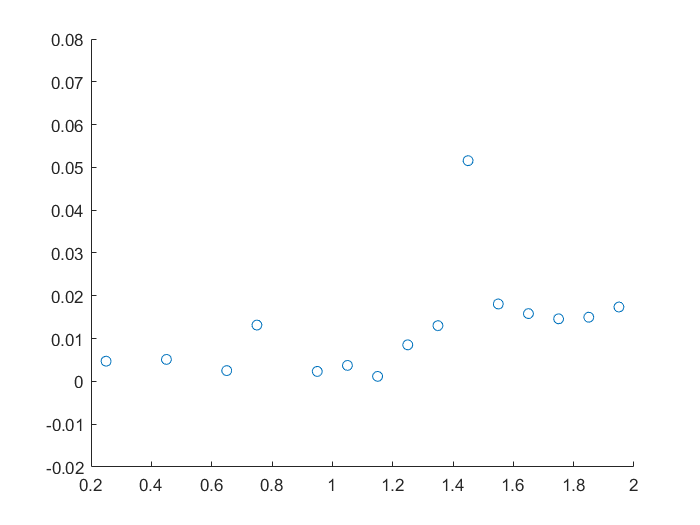


%Code partially provided by Jaap Nienhuis
%scatter plot V1
flux_ratio1(flux_ratio1<0) = 0; flux_ratio1(flux_ratio1>2) = 2; 
bin_edg = [0:0.1:2];
[y1] = discretize(flux_ratio1,bin_edg);
f_y1 = accumarray(y1,v1.ee.net_aqua,[],@mean);
scatter(bin_edg(1:end-1)+0.05,f_y1)
ylim ([-0.02 0.08])


%for replaced max 100
f_y1_replaced = accumarray(y1,v1.ee.net_max100replaced,[],@mean);


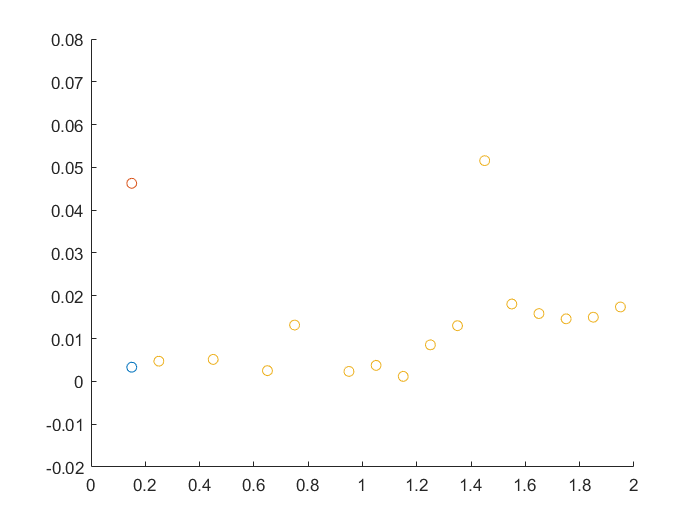

%replace yellow
No_Yellow_delta = v1.ee.net_aqua;
No_Yellow_delta(6302) = NaN;

Yellow_corr = No_Yellow_delta;
Yellow_corr(6302) = Max_deltas100_change(18);

clf
f_y_noyellow = accumarray(y1,No_Yellow_delta,[],@nanmean);
scatter(bin_edg(1:end-1)+0.05,f_y_noyellow)
ylim ([-0.02 0.08])
hold on
f_y_yellowcorr = accumarray(y1,Yellow_corr,[],@mean);
scatter(bin_edg(1:end-1)+0.05,f_y_yellowcorr)
ylim ([-0.02 0.08])
hold on
f_y1 = accumarray(y1,v1.ee.net_aqua,[],@mean);
scatter(bin_edg(1:end-1)+0.05,f_y1)
ylim ([-0.02 0.08])

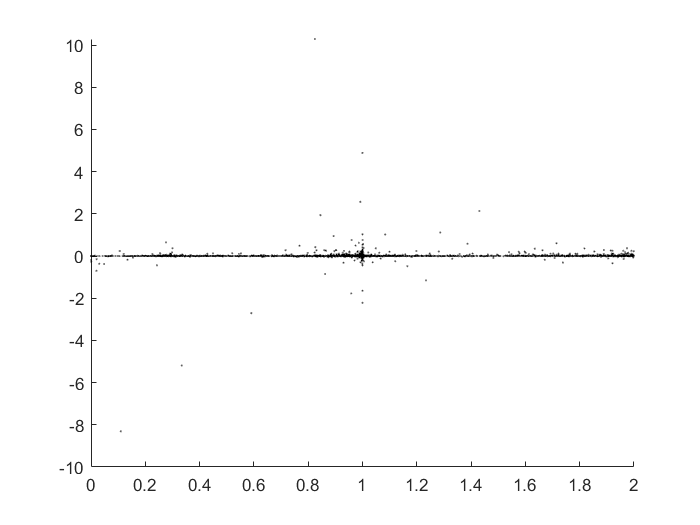

Ratio = v1.QRiver_dist./v1.QRiver_prist;
Ratio02log = Ratio >= 0 & Ratio <= 2;
Change0208log = v1.ee.net_aqua >= -0.02 & v1.ee.net_aqua <= 0.08;

%Linear regressions
%all data
v1_all_scatter = fitlm(Ratio, v1.ee.net_aqua)

v1_all_scatter = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE          tStat       pValue  
                   ___________    __________    _________    _________

    (Intercept)      0.0049892     0.0016854       2.9602    0.0030815
    x1             -2.9052e-13    1.5203e-11    -0.019109      0.98475


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.176
R-squared: 3.37e-08,  Adjusted R-Squared: -9.22e-05
F-statistic vs. constant model: 0.000365, p-value = 0.985

%for x between 0 and 2
v1_02_scatter = fitlm(Ratio(Ratio02log), v1.ee.net_aqua(Ratio02log))

v1_02_scatter = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    -0.014099    0.0053645    -2.6282     0.0085968
    x1              0.018429    0.0052252     3.5269    0.00042229


Number of observations: 9999, Error degrees of freedom: 9997
Root Mean Squared Error: 0.166
R-squared: 0.00124,  Adjusted R-Squared: 0.00114
F-statistic vs. constant model: 12.4, p-value = 0.000422

%with yellow corrected
v1_02yellowcor_scatter = fitlm(Ratio(Ratio02log), Yellow_corr(Ratio02log))

v1_02yellowcor_scatter = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE        tStat      pValue 
                   __________    _________    ______    ________

    (Intercept)    -0.0043395    0.0047015    -0.923     0.35603
    x1              0.0095011    0.0045794    2.0747    0.038037


Number of observations: 9999, Error degrees of freedom: 9997
Root Mean Squared Error: 0.146
R-squared: 0.00043,  Adjusted R-Squared: 0.00033
F-statistic vs. constant model: 4.3, p-value = 0.038

%With all data replaced
v1_all_scatterreplaced = fitlm(Ratio(Ratio02log), v1.ee.net_max100replaced(Ratio02log))

v1_all_scatterreplaced = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    ________    _______

    (Intercept)      0.012961    0.0090158      1.4376    0.15059
    x1             -0.0024798    0.0087816    -0.28238    0.77765


Number of observations: 9999, Error degrees of freedom: 9997
Root Mean Squared Error: 0.28
R-squared: 7.98e-06,  Adjusted R-Squared: -9.21e-05
F-statistic vs. constant model: 0.0797, p-value = 0.778


%Bins
%for v1 bins
v1_bins = fitlm(bin_edg(1:end-1)+0.05,f_y1)

v1_bins = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   _________    ________    _______    ________

    (Intercept)    -0.039539    0.018148    -2.1787    0.042886
    x1              0.040225    0.015721     2.5586     0.01974


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.0405
R-squared: 0.267,  Adjusted R-Squared: 0.226
F-statistic vs. constant model: 6.55, p-value = 0.0197


%for corrected yellow bins
v1_bins = fitlm(bin_edg(1:end-1)+0.05,f_y_yellowcorr)

v1_bins = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE        tStat      pValue 
                   __________    ________    ________    _______

    (Intercept)    -0.0023389    0.011684    -0.20017    0.84359
    x1               0.013485    0.010122      1.3323     0.1994


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.0261
R-squared: 0.0898,  Adjusted R-Squared: 0.0392
F-statistic vs. constant model: 1.77, p-value = 0.199


%for corrected max100 bins
v1_bins = fitlm(bin_edg(1:end-1)+0.05,f_y1_replaced)

v1_bins = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat       pValue 
                   _________    ________    ________    ________

    (Intercept)     0.045296    0.021291      2.1275    0.047461
    x1             -0.012239    0.018444    -0.66356     0.51538


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.0476
R-squared: 0.0239,  Adjusted R-Squared: -0.0304
F-statistic vs. constant model: 0.44, p-value = 0.515

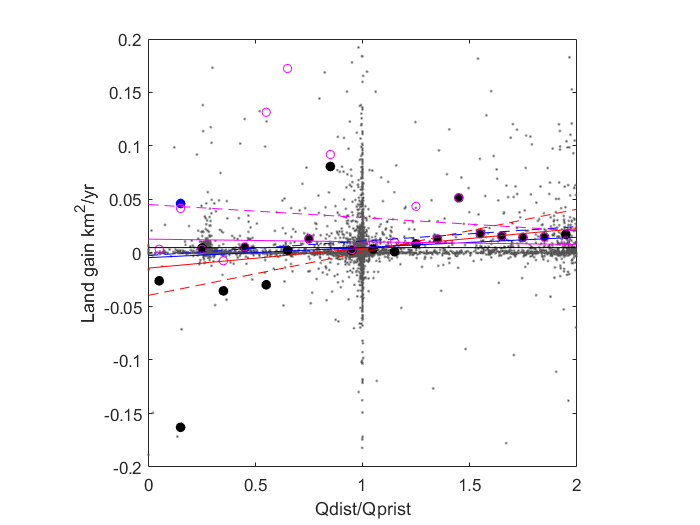

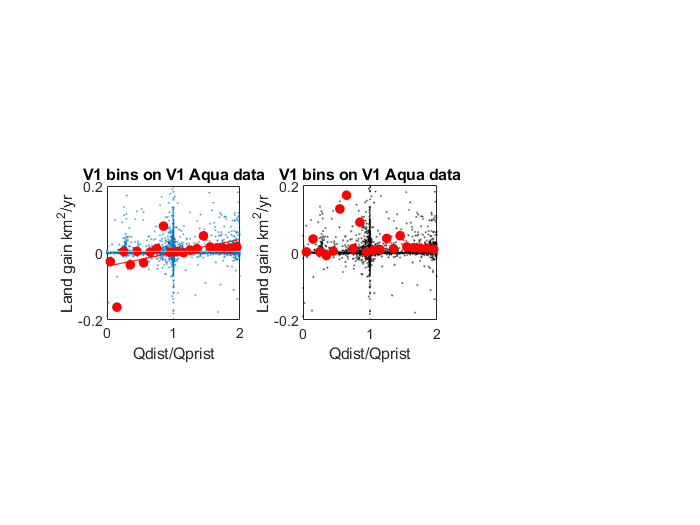

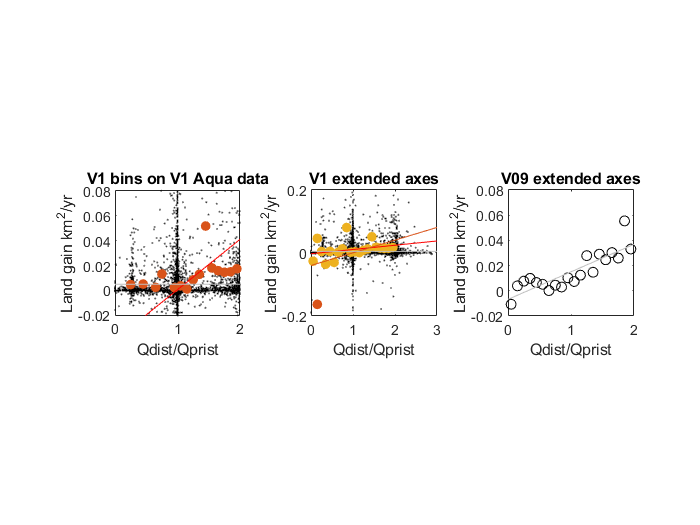

%Do Extended Fig 1aii plot
clf
scatter(Ratio(Ratio02log), v1.ee.net_aqua(Ratio02log), 12, [0.33 0.33 0.33], '.')
hold on
plot(bin_edg(1:end-1)+0.05,f_y_yellowcorr,'.', 'MarkerSize',20,"Color",'b')
plot(bin_edg(1:end-1)+0.05,f_y1,'.', 'MarkerSize',20,"Color",'k')
plot(bin_edg(1:end-1)+0.05,f_y1_replaced,'o', 'MarkerSize',5,"Color",'m')
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
%h1 = lsline(ax1);
%h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;

%add regression lines
p1 = polyfit(Ratio, v1.ee.net_aqua,1);
p2 = polyfit(Ratio(Ratio02log), v1.ee.net_aqua(Ratio02log),1);
p3 = polyfit(Ratio(Ratio02log), Yellow_corr(Ratio02log),1);
p4 = polyfit(Ratio(Ratio02log), v1.ee.net_max100replaced(Ratio02log),1);
p5 = polyfit(bin_edg(1:end-1)+0.05,f_y1,1); %for v1 bins
p6 = polyfit(bin_edg(1:end-1)+0.05,f_y_yellowcorr,1); %for yellowcor bins
p7 = polyfit(bin_edg(1:end-1)+0.05,f_y1_replaced,1); %for replaced bins

x1 = linspace(0,2);
y1 = polyval(p1,x1);
y2 = polyval(p2,x1);
y3 = polyval(p3,x1);
y4 = polyval(p4,x1);
y5 = polyval(p5,x1);
y6 = polyval(p6,x1);
y7 = polyval(p7,x1);

plot(x1,y1,'k')
plot(x1,y2,'r')
plot(x1,y3,'b')
plot(x1,y4,'m')
plot(x1,y5,'r--')
plot(x1,y6,'b--')
plot(x1,y7,'m--')

hold off


xlim([0 2])
ylim([-0.02 0.08])
ylim([-0.2 0.2])
xlabel 'Qdist/Qprist'
ylabel 'Land gain km^2/yr'
axis square
box on